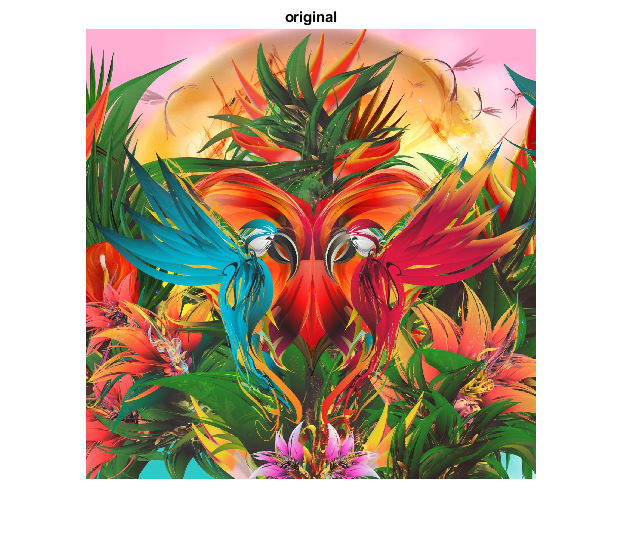

clc
clear
figure;
img_a=imread('parrot.jpg');
imshow(img_a); % Original image
title('original');

## Extract color components

im_red=double(img_a(:,:,1));
im_green=double(img_a(:,:,2));
im_blue=double(img_a(:,:,3));

## Encoding

QL=8;

error_r = DPCM_encoder(im_red, QL)*QL/256;
disp('elements in error_red are');

elements in error_red are


size(unique(error_r))

ans =      4     1


unique(error_r).'

ans =     -3    -1     1     3



error_g = DPCM_encoder(im_green, QL)*QL/256;
disp('elements in error_green are');

elements in error_green are


size(unique(error_g))

ans =      4     1


unique(error_g).'

ans =     -3    -1     1     3



error_b = DPCM_encoder(im_blue, QL)*QL/256;
disp('elements in error_blue are');

elements in error_blue are


size(unique(error_b))

ans =      4     1


unique(error_b).'

ans =     -3    -1     1     3


## Decoding

recon_red = DPCM_decoder((error_r)*256/QL);

recon_green = DPCM_decoder((error_g)*256/QL);

recon_blue = DPCM_decoder((error_b)*256/QL);

## Reconstruction

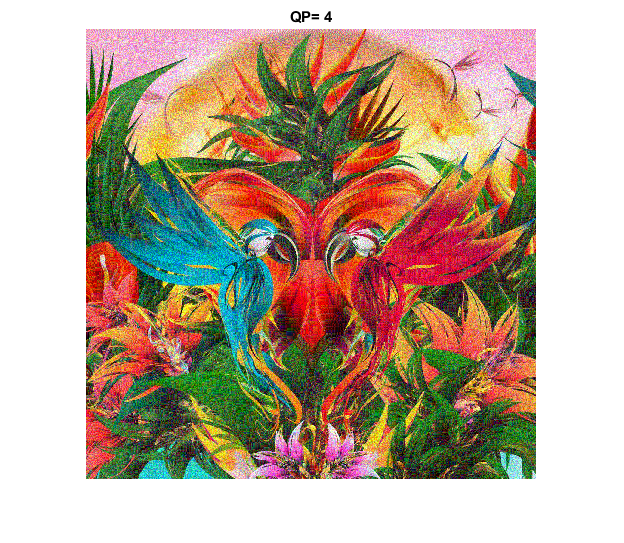

% Combine three color channels and display compressed image
imshow(uint8(cat(3,recon_red, recon_green, recon_blue)));
title('no. of Quntization levels= 4')